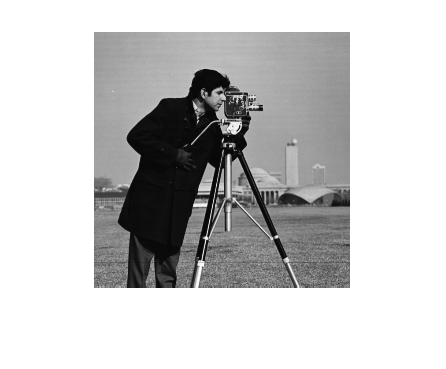

[img,cmap] = imread('images\cameraman.tif');
imshow([img,cmap])

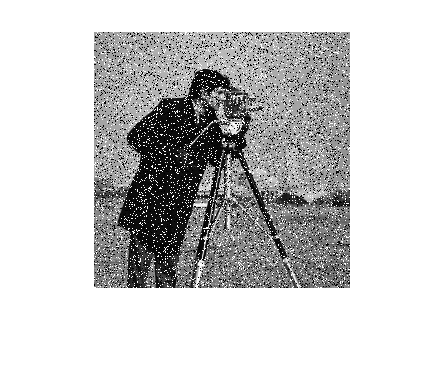

img = imnoise(img, 'salt & pepper',0.2);
imshow(img)

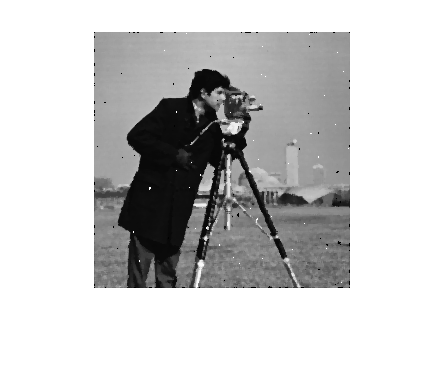

img = ordfilt2(img, 5, ones(3,3));
figure,imshow(img)

[img,cmap] = imread('images\cameraman.tif');
imshow([img,cmap])

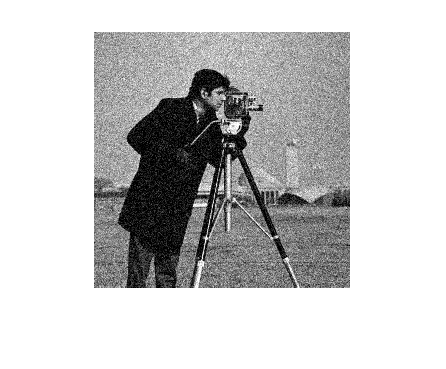

img = imnoise(img, 'gaussian');
imshow(img)

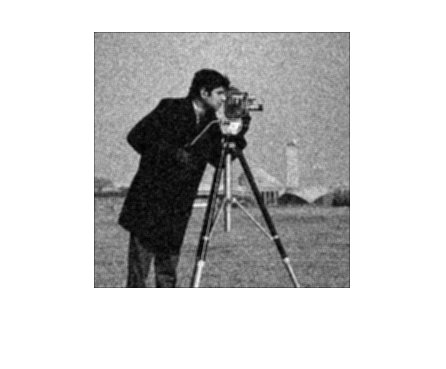

kernel_size = 3;
kernel = ones(kernel_size, kernel_size) ./ kernel_size^2;
img = imfilter(img, kernel, 'conv');
imshow(img)

[img,cmap] = imread('images\cameraman.tif');
imshow([img,cmap])

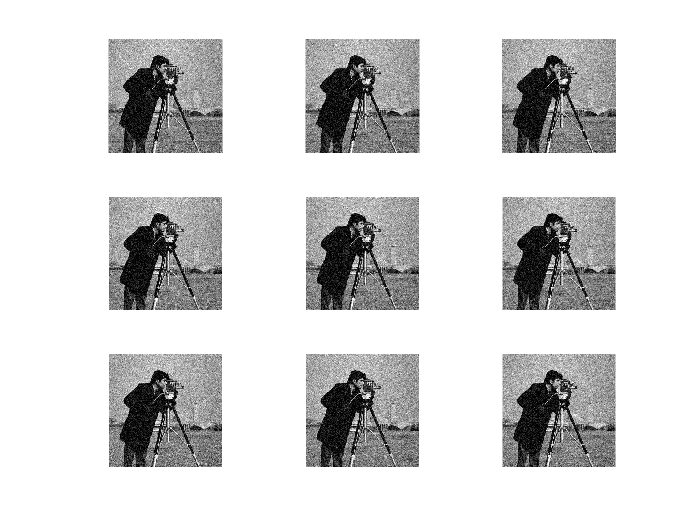

t = zeros([size(img), 5]);
figure;
for i=1:9
    subplot(3,3,i);
    t(:,:,i) = imnoise(img, 'gaussian');
    imshow(uint8(t(:,:,i)));
    axis image
end

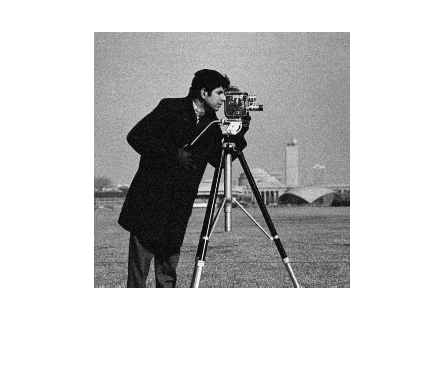

img_denoise = uint8(mean(t,3));
figure,imshow(img_denoise);

[img,cmap] = imread('images\cameraman.tif');
imshow([img,cmap])

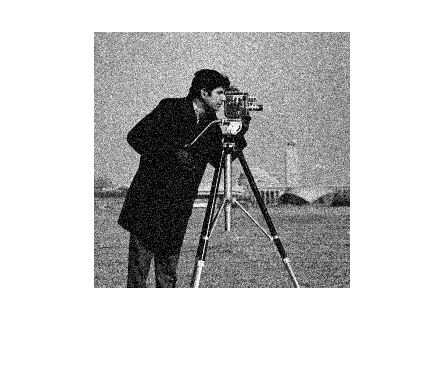

img = imnoise(img, 'gaussian');
imshow(img)

kernel = ones(3, 3) ./ 8; kernel(5) = 0;
disp(kernel);

    0.1250    0.1250    0.1250
    0.1250         0    0.1250
    0.1250    0.1250    0.1250



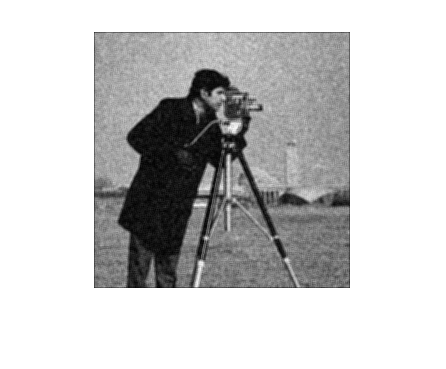

img_comp = imfilter(img, kernel, 'conv');
imshow(img_comp)

diff = int8(abs(img - img_comp) < 50)

diff = 256×256 int8 matrix
   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   0   1   1   0   0   0   1   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   0   1   1   1   1   0   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

diff2 = int8(abs(img - img_comp) >= 50)

diff2 = 256×256 int8 matrix
   1   1   1   1   0   1   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   0   1   0   1   1   1   1   1   1   1   1   1   1   1   0   0   1   0   1   0   0   1   1   1   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   1   0   0   0   0   1   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

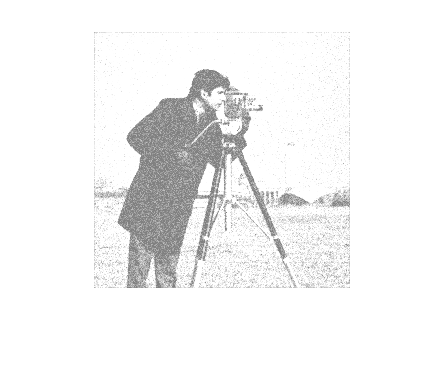

imgnew = int8(img) .* diff + int8(img_comp) .* diff2;
imshow(imgnew)